clear all

## Load task Files

T = readtable('../task_track_files/task_track_file_matlab_linux_double_calculation_Habituation.csv','Format','%d%s%s%s%s%s%s%s%s%s%s%s')

T = 75×12 table
    Var1        local_file_path                 raw_data_file_name                            preprocessed_two                                       ERP_mat_file                                           ERP_npy_file                               ERP_npy_file_with_normalization_and_baseline_correction                           ERP_nobaseline_npy_file                                       Cavanagh_habituation_signals                                                 Limpel_Ziv_over_channels                                        P300_over_all_channels_without_normalization             Group_file_type
    ____    _______________________    ____________________________________    _____________________________________

### Create Stimulus String Cell

trial_number = 192;
Path = '/mnt/D/Mastersharif/MasterProject/data/parkinsons-oddball';
collected_index_stimulus = cell(75,1);
a = T{:,2};
b = T{:,4};
c = T{:,10};
d = T{:,12};
counter_ctl = 1;
counter_PD_on = 1;
counter_PD_off = 1;
Stimulus_number = zeros(75,1);
main_stimuli_name = {'S200','S201','S202'};
for i=12
    load_path = fullfile(Path,T{i,2}{1}); %sprintf('%s/%s',Path,a{i});
    
%     if ~isfile(fullfile(load_path,c{i}))
%         EEG = pop_loadset(b{i},load_path);
%         EEG = pop_runica(EEG, 'icatype', 'runica', 'extended',1,'interrupt','off','maxsteps',250,'stop',0.0001);
%     
% %     EEG_ica_path = fullfile(Path,a{i})
%         pop_saveset(EEG,'filename',c{i},'filepath',load_path)
%     else
%         EEG = pop_loadset(c{i},load_path);
%     en
    EEG = pop_loadset(T{i,4}{1},load_path);
    % Calculation Limpelziv Matrix channels * trials
    downsample_factor = 1;
    IC = EEG.data(:,:);
    num_component = size(IC,1)
    

    a1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{1})==1,1);
    b1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{2})==1,1);
    c1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{3})==1,1);
    first_stimulus = min([a1,b1,c1]);
    start_index = first_stimulus-1;
    % 121 calculate
    num_trials = size(EEG.event,2)-start_index;
    time_index = zeros(1,num_trials);
    Stimulus_number(i) = num_trials;
    index_s200 = find(strcmp({EEG(1).event(first_stimulus:first_stimulus+num_trials-1).type},main_stimuli_name{1})==1); 
    index_s201 = find(strcmp({EEG(1).event(first_stimulus:first_stimulus+num_trials-1).type},main_stimuli_name{2})==1);
    index_s202 = find(strcmp({EEG(1).event(first_stimulus:first_stimulus+num_trials-1).type},main_stimuli_name{3})==1);
    temp =  zeros(1,num_trials);
    temp(index_s200) = 0;
    temp(index_s201) = 1;
    temp(index_s202) = 2;
    collected_index_stimulus{i} = temp;
end

Subject_type = T{:,12}

Subject_type = 75×1 cell array
    {'PD_ON' }
    {'PD_OFF'}
    {'PD_ON' }
    {'PD_OFF'}
    {'CTL'   }
    {'PD_OFF'}
    {'PD_ON' }
    {'CTL'   }
    {'PD_OFF'}
    {'PD_ON' }
    {'PD_OFF'}
    {'PD_ON' }
    {'PD_ON' }
    {'PD_OFF'}
    {'PD_ON' }
    {'PD_OFF'}
    {'PD_ON' }
    {'PD_OFF'}
    {'PD_OFF'}
    {'PD_ON' }
    {'PD_ON' }
    {'PD_OFF'}
    {'PD_ON' }
    {'PD_OFF'}
    {'PD_OFF'}
    {'PD_ON' }
    {'PD_OFF'}
    {'PD_ON' }
    {'PD_ON' }
    {'PD_OFF'}


save('Subject_type.mat',"Subject_type")

### Save stimulus_number

save('collected_index_stimulus.mat','collected_index_stimulus')

### Find the outlier Latency to find the possible missed stimulus index in the original sitmulus sequeces.

trial_number = 192;
Path = '/mnt/D/Mastersharif/MasterProject/data/parkinsons-oddball';
Latencies = cell(75,1);
a = T{:,2};
b = T{:,4};
c = T{:,10};
d = T{:,12};
counter_ctl = 1;
counter_PD_on = 1;
counter_PD_off = 1;
Stimulus_number = zeros(75,1);

main_stimuli_name = {'S200','S201','S202'};
for i=1:75
    load_path = fullfile(Path,T{i,2}{1}); %sprintf('%s/%s',Path,a{i});
    
%     if ~isfile(fullfile(load_path,c{i}))
%         EEG = pop_loadset(b{i},load_path);
%         EEG = pop_runica(EEG, 'icatype', 'runica', 'extended',1,'interrupt','off','maxsteps',250,'stop',0.0001);
%     
% %     EEG_ica_path = fullfile(Path,a{i})
%         pop_saveset(EEG,'filename',c{i},'filepath',load_path)
%     else
%         EEG = pop_loadset(c{i},load_path);
%     en
    EEG = pop_loadset(T{i,4}{1},load_path);
    % Calculation Limpelziv Matrix channels * trials
    downsample_factor = 1;
    IC = EEG.data(:,:);
    num_component = size(IC,1)
    

    a1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{1})==1,1);
    b1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{2})==1,1);
    c1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{3})==1,1);
    first_stimulus = min([a1,b1,c1]);
    start_index = first_stimulus-1;
    % 121 calculate
    temp = [EEG(1).event(first_stimulus:end).latency];
    Latencies{i} = temp(2:end)-temp(1:end-1);
end

### Save Latencies

save("Latencies.mat",'Latencies')

## Find the index of Blocks

valid_subject = setdiff([1:75],[15]);
Index_end_first_block = zeros(75,1);
for i=1:75
    [B,I] = sort(Latencies{i},'descend');
    Index_end_first_block(i,1) = I(1); 
end

### Save the end index of Block

save('Index_end_first_block.mat','Index_end_first_block')

valid_subject = setdiff([1:75],[12,60,15,22]);
filled_collected_index_stimulus_sub_block_1 = cell(75,1);
for i=valid_subject
    [B,I] = sort(Latencies{i},'descend');
    I = I(2:1+200-size(Latencies{i},2)-1);
%     I = sort(I);
    I = sort(I)+1;
    num_index = size(I,2);
    for j=0:3^(num_index)-1
        t=dec2base(j,3,num_index);
        start = 1;
        c = [];
        for k=1:num_index 
            c = [c, collected_index_stimulus{i}(start:I(k)-1), str2num(t(k))]; 
            start = I(k);
        end
        c = [c,collected_index_stimulus{i}(start:start+200-size(c,2)-1)];
%         Flags = [construct(c(1:48)),construct(c(49:96)),strcmp(c(97:100),[1,2,1,0]),construct(c(101:148)),construct(c(149:196)),strcmp(c(197:200),[1,2,1,0])]
        if construct(c(1:48)) & construct(c(49:96)) & all(c(97:100)==[1,2,1,0]) & construct(c(101:148)) & construct(c(149:196)) & all(c(197:200)==[1,2,1,0])
            filled_collected_index_stimulus_sub_block_1{i,1} = [filled_collected_index_stimulus_sub_block_1(i,1),c];   
        end
    end
end

save('resconstructed_stimulus.mat','filled_collected_index_stimulus_sub_block')

I_three_subs = cell(1,3);
counter = 1

counter = 1

for i=[12,22,60]
    [B,I] = sort(Latencies{i},'descend');
    I_three_subs{counter} = I(2:1+200-size(Latencies{i},2)-1);
    counter = counter + 1;
end 


sub12 = collected_index_stimulus{12};
sub22 = collected_index_stimulus{22};
sub60 = collected_index_stimulus{60};



for k=[0,1,2]

i = 22

    c = [sub22(1:28),1,1,sub22(29:48),sub22(49:80),k,sub22(81:197)];
    if construct(c(1:48)) & construct(c(49:96)) & all(c(97:100)==[1,2,1,0]) & construct(c(101:148)) & construct(c(149:196)) & all(c(197:200)==[1,2,1,0])
         filled_collected_index_stimulus_sub_block{i,1} = [filled_collected_index_stimulus_sub_block(i,1),c];   
    end
end

i = 12

i = 12

for k=[0,1,2]
    c = [sub12(1:48),sub12(49:61),1,1,sub12(62:88),k,sub12(89:197)];
    if construct(c(1:48)) & construct(c(49:96)) & all(c(97:100)==[1,2,1,0]) & construct(c(101:148)) & construct(c(149:196)) & all(c(197:200)==[1,2,1,0])
            filled_collected_index_stimulus_sub_block{i,1} = [filled_collected_index_stimulus_sub_block(i,1),c];   
    end 
end

% sub12_filled = [sub12(1:48),sub12(49:61),1,1,sub12(62:88),1,sub12(89:197)];

f=0

f = 0

for k=[0,1,2]
    c = [sub22(1:28),1,2,sub22(29:48),sub22(49:80),k,sub22(81:197)];
    if construct(c(1:48)) & construct(c(49:96)) & all(c(97:100)==[1,2,1,0]) & construct(c(101:148)) & construct(c(149:196)) & all(c(197:200)==[1,2,1,0])
        f=1
    end
end 

f=0

f = 0

for k=[0,1,2]
    c = [sub12(1:48),sub12(49:61),0,2,sub12(62:88),k,sub12(89:197)];
    if construct(c(1:48)) & construct(c(49:96)) & all(c(97:100)==[1,2,1,0]) & construct(c(101:148)) & construct(c(149:196)) & all(c(197:200)==[1,2,1,0])
           f=1  
    end 
end

i=60

i = 60

d = [];
for k=0:3^5-1
     t = dec2base(k,3,5);
     c = [sub60(1:62),str2num(t(1)),sub60(63:69),str2num(t(2)),str2num(t(3)),sub60(70:77),str2num(t(4)),sub60(78:118),str2num(t(5)),sub60(119:195)];
     if construct(c(1:48)) & construct(c(49:96)) & all(c(97:100)==[1,2,1,0]) & construct(c(101:148)) & construct(c(149:196)) & all(c(197:200)==[1,2,1,0])
%            filled_collected_index_stimulus_sub_block_1{i,1} = [filled_collected_index_stimulus_sub_block_1(i,1),c];   
            d = [d,c]; 
            t_final = t
     end 
end

t_final = '11111'

i=12

i = 12

d =[]


d =

     []




for k=0:3^3-1
     t = dec2base(k,3,3);
     c = [sub12(1:48),sub12(49:62),str2num(t(1)),str2num(t(2)),sub12(63:89),str2num(t(3)),sub12(90:197)];
     if construct(c(1:48)) & construct(c(49:96)) & all(c(97:100)==[1,2,1,0]) & construct(c(101:148)) & construct(c(149:196)) & all(c(197:200)==[1,2,1,0])
        d = [d,c];   
        t_final = t
     end 
end

t_final = '111'

i=22

i = 22

d =[];
for k=0:3^3-1
     t = dec2base(k,3,3);
     c = [sub22(1:29),str2num(t(1)),str2num(t(2)),sub22(30:47),sub22(48:81),str2num(t(3)),sub22(82:197)];
     if construct(c(1:48)) & construct(c(49:96)) & all(c(97:100)==[1,2,1,0]) & construct(c(101:148)) & construct(c(149:196)) & all(c(197:200)==[1,2,1,0])
        d = [d,c];   
        t = t_final
     end 
end

t = '111'

save('resconstructed_stimulus.mat','filled_collected_index_stimulus_sub_block')

reconstructed_stimulus_sequences = cell(75,1);
for i=1:75
    if i ~= 15
        reconstructed_stimulus_sequences{i} = filled_collected_index_stimulus_sub_block{i}{1,2}; 
    end     
end


save('reconstructed_stimulus.mat','reconstructed_stimulus_sequences')

f=0

f = 0

for i=1:75
    if i ~= 15
        c = reconstructed_stimulus_sequences{i};
        if construct(c(1:48)) & construct(c(49:96)) & all(c(97:100)==[1,2,1,0]) & construct(c(101:148)) & construct(c(149:196)) & all(c(197:200)==[1,2,1,0])
           f = f + 1;
        end
    end    
end

valid_subject = setdiff([1:75],[12,60,15,22]);

I2 = cell(75,1);
for i=valid_subject
    [B,t] = sort(Latencies{i},'descend');
    t = t(2:1+200-size(Latencies{i},2)-1);
%     I2{i} = sort(t)+[0:size(t,2)-1];
    I2{i} = sort(t)+[0:size(t,2)-1]+1;
end    

d = cell(75,1);
for i = [12,22,60]
    [B,t] = sort(Latencies{i},'descend');
    t = t(2:1+200-size(Latencies{i},2)-1-1);% the big latency is considered as two stimulus for 22,12,60
    t = [t(1),t];
    t = sort(t);
%     I2{i} = t + [0:size(t,2)-1];
    d{i} = t + [0:size(t,2)-1]+1;   
end

save('index_surprise_should_be_removed_corrected.mat','I2')

[B,t] = sort(Latencies{1},'descend');
t = t(2:1+200-size(Latencies{1},2)-1-1);
t = sort(t)

t =      7    49   122   182


i=60

i = 60

% for k=0:3^5-1
t = t_final;
c1 = [sub60(1:61),str2num(t(1)),sub60(62:68),str2num(t(2)),str2num(t(3)),sub60(69:76),str2num(t(4)),sub60(77:117),str2num(t(5)),sub60(118:195)];
%      if construct(c(1:48)) & construct(c(49:96)) & all(c(97:100)==[1,2,1,0]) & construct(c(101:148)) & construct(c(149:196)) & all(c(197:200)==[1,2,1,0])
%            filled_collected_index_stimulus_sub_block_1{i,1} = [filled_collected_index_stimulus_sub_block_1(i,1),c];   
%      end 
% end

i=60

i = 60

% for k=0:3^5-1
t = t_final;
c2 = [sub60(1:62),str2num(t(1)),sub60(63:69),str2num(t(2)),str2num(t(3)),sub60(70:77),str2num(t(4)),sub60(78:118),str2num(t(5)),sub60(119:195)];
%      if construct(c(1:48)) & construct(c(49:96)) & all(c(97:100)==[1,2,1,0]) & construct(c(101:148)) & construct(c(149:196)) & all(c(197:200)==[1,2,1,0])
%            filled_collected_index_stimulus_sub_block_1{i,1} = [filled_collected_index_stimulus_sub_block_1(i,1),c];   
%      end 
% end

i=22

i = 22

% for k=0:3^3-1
 t = t_final

t = '111'

 c1 = [sub22(1:28),str2num(t(1)),str2num(t(2)),sub22(29:47),sub22(48:80),str2num(t(3)),sub22(81:197)];
%      if construct(c(1:48)) & construct(c(49:96)) & all(c(97:100)==[1,2,1,0]) & construct(c(101:148)) & construct(c(149:196)) & all(c(197:200)==[1,2,1,0])
%            filled_collected_index_stimulus_sub_block_1{i,1} = [filled_collected_index_stimulus_sub_block_1(i,1),c];   
%      end 
% end

i=22

i = 22

% for k=0:3^3-1
t = t_final

t = '111'

c2 = [sub22(1:29),str2num(t(1)),str2num(t(2)),sub22(30:47),sub22(48:81),str2num(t(3)),sub22(82:197)];
%      if construct(c(1:48)) & construct(c(49:96)) & all(c(97:100)==[1,2,1,0]) & construct(c(101:148)) & construct(c(149:196)) & all(c(197:200)==[1,2,1,0])
%            filled_collected_index_stimulus_sub_block_1{i,1} = [filled_collected_index_stimulus_sub_block_1(i,1),c];   
%      end 
% end

i=12

i = 12

c =[]


c =

     []




% for k=0:3^3-1
t = t_final

t = '111'

c1 = [sub12(1:47),sub12(48:61),str2num(t(1)),str2num(t(2)),sub12(62:88),str2num(t(3)),sub12(89:197)];
%      if construct(c(1:48)) & construct(c(49:96)) & all(c(97:100)==[1,2,1,0]) & construct(c(101:148)) & construct(c(149:196)) & all(c(197:200)==[1,2,1,0])
%           filled_collected_index_stimulus_sub_block_1{i,1} = [filled_collected_index_stimulus_sub_block_1(i,1),c];   
%      end 
% end

i=12

i = 12

c =[]


c =

     []




% for k=0:3^3-1
t = t_final

t = '111'

c2 = [sub12(1:48),sub12(49:62),str2num(t(1)),str2num(t(2)),sub12(63:89),str2num(t(3)),sub12(90:197)];
%      if construct(c(1:48)) & construct(c(49:96)) & all(c(97:100)==[1,2,1,0]) & construct(c(101:148)) & construct(c(149:196)) & all(c(197:200)==[1,2,1,0])
%           filled_collected_index_stimulus_sub_block_1{i,1} = [filled_collected_index_stimulus_sub_block_1(i,1),c];   
%      end 
% end

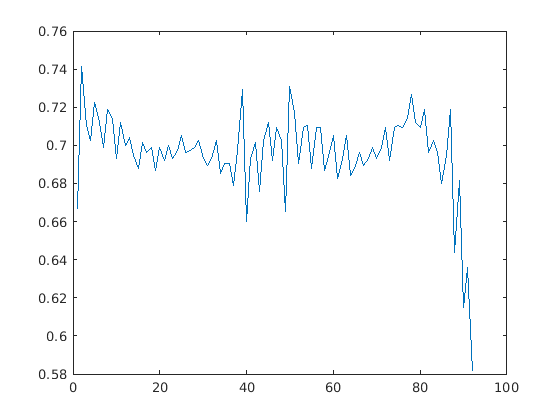

len1 = 10;
w = ones(1,len1)/len1;
a = zeros(75,92);
for i=1:75
  if i ~= 15  
      temp = [reconstructed_stimulus_sequences{i}(100:200)==1];
      a(i,:) = conv(temp,w,"valid");
  end
end 
plot(mean(a,1))

Calcualtion of surprise Three State KL on stimulus on stimulus

Path_save_data = 'D:\Mastersharif\MasterProject\Surprise\Codes\brainsurprise2\brainsurprise\Results\SurpriseCalculations\Completed'

Path_save_data = 'D:\Mastersharif\MasterProject\Surprise\Codes\brainsurprise2\brainsurprise\Results\SurpriseCalculations\Completed'

Three_state_KL_stimulus_complete = zeros(75,200);
for i=1:size(reconstructed_stimulus_sequences,1)
    Three_state_KL_stimulus_complete(i,:) = three_state_KL_on_stimulus(reconstructed_stimulus_sequences{i}'+1,10)';
end

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete =          0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325    0.0026    0.0041    0.0030    0.0071    0.0079    0.0036    0.0161    0.0008    0.0041    0.0030    0.0022    0.0231    0.0092    0.0029    0.0216    0.0027    0.0035    0.0010    0.0195    0.0040
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069    0.0100    0.0060    0.0042    0.0007    0.0102    0.0046    0.0051    0.0050    0.0150    0.0396    0.0067    0.0047    0.0034    0.0025    0.0070    0.0160    

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0

Three_state_KL_stimulus_complete = 75×200
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0050    0.0111    0.0130    0.0223    0.0141    0.0083    0.0018    0.0293    0.0076    0.0254    0.0682    0.0071    0.0048    0.0532    0.0066    0.0050    0.0035    0.0026    0.0019    0.0345    0.0206    0.0325
         0    0.0566    0.0589    0.0398    0.0237    0.0758    0.0121    0.0148    0.0080    0.0048    0.0437    0.0279    0.0053    0.0662    0.0144    0.0055    0.0021    0.0148    0.0057    0.0039    0.0091    0.0328    0.0044    0.0032    0.0770    0.0199    0.0037    0.0039    0.0074    0.0069
         0   -0.0000    0.0488    0.0553    0.0200    0.0873    0.0188    0.0134    0.0106    0.0085    0.0104    0.0063    0.0084    0.0289    0.0063    0.0248    0.0638    0.0063    0.0712    0.0108    0.0061    0.0042    0.0030    0.0022    0.0500    0.0189    0.0029    0.0290    0.0062    0.0022
         0    0.0566    0.0173    0.0073    0.2093    0